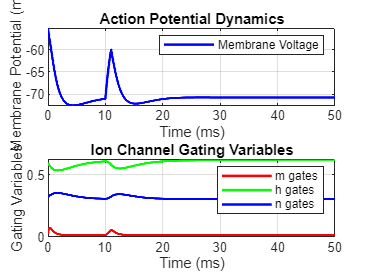

% Hodgkin-Huxley Model Simulation of Action Potential
% Parameters initialization
C = 1.0; % Membrane capacitance per unit area (µF/cm^2)
gNabar = 120; % Maximum Na+ conductance (µA/mV/cm^2)
gKbar = 36; % Maximum K+ conductance (µA/mV/cm^2)
gLbar = 0.3; % Leakage conductance (µA/mV/cm^2)
ENa = 45; % Na+ equilibrium potential (mV)
EK = -82; % K+ equilibrium potential (mV)
EL = -59; % Leakage reversal potential (mV)
dt = 0.01; % Time step (ms)
tmax = 50; % Experiment duration (ms)
klokmax = ceil(tmax/dt); % Total number of time steps
vhold = -70; % Resting potential (mV)
vstart = vhold + 15; % Voltage after shock (mV)
t1p = 10; % Time of second shock (ms)
t2p = t1p + 1; % Duration (ms)
ip = 15; % Applied current (µA)

% Initializing variables
v = vhold;
t = 0;
m = alpham(v)/(alpham(v) + betam(v));
h = alphah(v)/(alphah(v) + betah(v));
n = alphan(v)/(alphan(v) + betan(v));
mhn_plot = zeros(3, klokmax);
v_plot = zeros(1, klokmax);
t_plot = zeros(1, klokmax);

% Simulating the Hodgkin-Huxley model
for klok = 1:klokmax
    t = (klok - 1) * dt;
    
    % Current injection
    if t >= 0 && t < dt
        v = vstart;
    elseif t >= t1p && t < t2p
        v = v + ip * dt / C;
    end

    % Update gating variables
    m = m + dt * (alpham(v) * (1 - m) - betam(v) * m);
    h = h + dt * (alphah(v) * (1 - h) - betah(v) * h);
    n = n + dt * (alphan(v) * (1 - n) - betan(v) * n);

    % Calculate conductances
    gNa = gNabar * m^3 * h;
    gK = gKbar * n^4;
    gL = gLbar;

    % Membrane potential update
    INa = gNa * (v - ENa);
    IK = gK * (v - EK);
    IL = gL * (v - EL);
    dv = (-INa - IK - IL) / C;
    v = v + dt * dv;

    % Storing values for plotting
    v_plot(klok) = v;
    t_plot(klok) = t;
    mhn_plot(:, klok) = [m; h; n];
end

% Plotting results
figure;
subplot(2,1,1);
plot(t_plot, v_plot, 'b', 'LineWidth', 1.5);
title('Action Potential Dynamics');
xlabel('Time (ms)');
ylabel('Membrane Potential (mV)');
legend('Membrane Voltage');
grid on;

subplot(2,1,2);
plot(t_plot, mhn_plot(1,:), 'r', t_plot, mhn_plot(2,:), 'g', t_plot, mhn_plot(3,:), 'b', 'LineWidth', 1.5);
title('Ion Channel Gating Variables');
xlabel('Time (ms)');
ylabel('Gating Variables');
legend('m gates', 'h gates', 'n gates');
grid on;


% Functions for alpha and beta values
function a = alphah(v)
    theta = (v + 70) / 20;
    a = 0.07 * exp(-theta);
end

function a = betah(v)
    theta = (v + 40) / 10;
    a = 1.0 / (1 + exp(-theta));
end

function a = alpham(v)
    theta = (v + 45) / 10;
    if theta == 0
        a = 1.0;
    else
        a = theta / (1 - exp(-theta));
    end
end

function a = betam(v)
    theta = (v + 50) / 18;
    a = 4.0 * exp(-theta);
end

function a = alphan(v)
    theta = (v + 60) / 10;
    if theta == 0
        a = 0.1;
    else
        a = 0.1 * theta / (1 - exp(-theta));
    end
end

function a = betan(v)
    theta = (v + 70) / 80;
    a = 0.125 * exp(-theta);
end